% image
imageFolder = 'imagethree/cu_0.025/';
imageFiles = dir(fullfile(imageFolder, '*.png')); % フォーマットに応じて変更
imgcnt = 3;
imagePath = fullfile(imageFolder, imageFiles(imgcnt).name);
%color space
cform1 = makecform('xyz2xyl')

cform1 = フィールドをもつ struct :
            c_func: @xyz2xyl
     ColorSpace_in: 'xyz'
    ColorSpace_out: 'xyl'
          encoding: 'double'
             cdata: [1×1 struct]


cform2 = makecform('xyl2xyz')

cform2 = フィールドをもつ struct :
            c_func: @xyl2xyz
     ColorSpace_in: 'xyl'
    ColorSpace_out: 'xyz'
          encoding: 'double'
             cdata: [1×1 struct]


%callibration
callibration_Path = 'callibration/'

callibration_Path = 'callibration/'

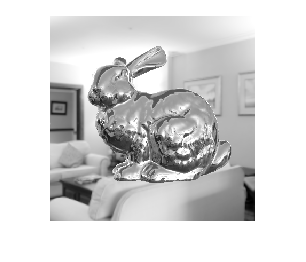

spectrum_data = readmatrix(fullfile(callibration_Path,'spectr.csv'));
c = tnt.RgbConverter(spectrum_data);
gamma_converter =load(fullfile(callibration_Path,"gamma_converter.mat")).gamma_converter;

%---finalize2---
originalImg = double(imread(imagePath));
srgbImgin = cat(3,originalImg(:,:,1)/255,originalImg(:,:,2)/255,originalImg(:,:,3)/255);
xyzImgin = rgb2xyz(srgbImgin);
xyYImgin = applycform(xyzImgin,cform1);
Ychan = xyYImgin(:,:,3);
lum_av = mean(Ychan(:));

originalImg2 = imread(imagePath);
imshow(originalImg2);


%{
disp(lum_av);
figure;
histogram(Ychan(:), 'Normalization', 'probability');
title('Three linear-srgb tonemapped');
xlabel('輝度値');
ylabel('頻度(正規化)');
%}
imshow(srgbImgin);

%---finalize2---
%---finalize---
%{
originalImg = double(imread(imagePath));
srgbImgin = cat(3,originalImg(:,:,1)/255,originalImg(:,:,2)/255,originalImg(:,:,3)/255);
xyzImgin = rgb2xyz(srgbImgin);
xyYImgin = applycform(xyzImgin,cform1);
Ychan = xyYImgin(:,:,3);

lum_av = mean(Ychan(:));
disp(lum_av);
figure;
histogram(Ychan(:), 'Normalization', 'probability');
title('Three linear-srgb tonemapped');
xlabel('輝度値');
ylabel('頻度(正規化)');

imshow(srgbImgin);
%}
%---finalize---
%---input sRGB already tonemapped---
%{
originalImg = double(imread(imagePath));
srgbImgin = cat(3,originalImg(:,:,1)/255,originalImg(:,:,2)/255,originalImg(:,:,3)/255);
xyzImgin = rgb2xyz(srgbImgin);
xyYImgin = applycform(xyzImgin,cform1);
Ychan = xyYImgin(:,:,3)
LDR_Y = Ychan*120 %ディスプレイの最大輝度の60%くらい;

lum_av = mean(Ychan(:));
disp(lum_av);
figure;
histogram(Ychan(:), 'Normalization', 'probability');
title('Three linear-srgb tonemapped');
xlabel('輝度値');
ylabel('頻度(正規化)');

xyYImgout = cat(3,xyYImgin(:,:,1),xyYImgin(:,:,2),LDR_Y);
xyzImgout = applycform(xyYImgout,cform2);
linear_rgb = c.xyz_to_linear_rgb(xyzImgout);
digital_rgb = gamma_converter.linear_rgb_to_digital_rgb(linear_rgb);
output_rgb = uint8(digital_rgb*255)

xyzImgout2  = rgb2xyz(output_rgb);
xyzImgcom = rgb2xyz(digital_rgb);
xyYImgcom = applycform(xyzImgcom,cform1);
Ychan_com = xyYImgcom(:,:,3);
lum_av = mean(Ychan_com(:));
disp(lum_av);
figure;
histogram(Ychan_com(:), 'Normalization', 'probability');
title('Three non-linear(callibrated) tonemapped');
xlabel('輝度値');
ylabel('頻度(正規化)');

%histogram
%{
figure;
h1 = histogram(Ychan(:), 'Normalization', 'probability');
hold on;
h2 = histogram(Ychan_com(:), 'Normalization', 'probability');
h1.FaceColor = 'r';
h2.FaceColor = 'b';
h1.FaceAlpha = 0.5;
h2.FaceAlpha = 0.5;
title('Three');
xlabel('輝度値');
ylabel('頻度');
legend('before', 'after');
hold off;
%}
rgbImgout = xyz2rgb(xyzImgout);
imshow(srgbImgin);
imshow(digital_rgb);
imshow(rgbImgout,[]);
%}
%---input sRGB already tonemapped---
%---input sRGB don't tonemapped---
%{
originalImg = double(imread(imagePath));
srgbImgin = cat(3,originalImg(:,:,1)/255,originalImg(:,:,2)/255,originalImg(:,:,3)/255);
xyzImgin = rgb2xyz(srgbImgin);
xyYImgin = applycform(xyzImgin,cform1);
xyYImgin(:,:,1) = 0.3127;
xyYImgin(:,:,2) = 0.3290;
%LDR_Y = xyYImgin(:,:,3)*100;
%LDR_Y = ReinhardTMO(xyYImgin(:,:,3))*100;
%LDR_Y = ReinhardTMO(xyYImgin(:,:,3),1,1,'global',8,1.19)*100;
LDR_Y = Reinhard(xyYImgin(:,:,3),1)*100;
xyYImgout = cat(3,xyYImgin(:,:,1),xyYImgin(:,:,2),LDR_Y);
xyzImgout = applycform(xyYImgout,cform2);
linear_rgb = c.xyz_to_linear_rgb(xyzImgout);
digital_rgb = gamma_converter.linear_rgb_to_digital_rgb(linear_rgb);
%}
%---input sRGB don't tonemapped---
% confirm
%{
max(max(max(linear_rgb)))
min(min(min(linear_rgb)))

max(max(max(digital_rgb)))
min(min(min(digital_rgb)))
%}